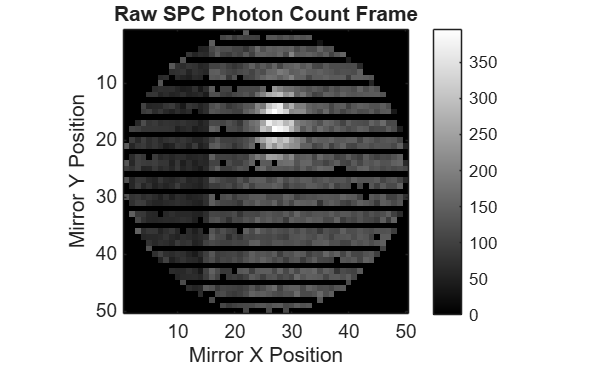

%% ============================================================
% SINGLE PHOTON CAMERA REAL DATA RECONSTRUCTION
% Mirror Position -> SPC Frame -> Richardson-Lucy
% ============================================================

clear; clc; close all


%% ============================================================
% READ PHOTON COUNT CSV
% ============================================================

folder = '\\userfs\bh1308\w2k\Desktop\Single Photon Camera\CSV\';

filename = uigetfile(fullfile(folder,'*.csv'),...
    'Select Photon Scan file');

data = readtable(fullfile(folder, filename));


%% ============================================================
% EXTRACT DATA
% ============================================================

mirrorX = data.X;          % Mirror X position
mirrorY = data.Y;          % Mirror Y position
Counts  = data.Count;      % Photon counts



%% ============================================================
% SCAN PARAMETERS
% Same as mirror raster scan
% ============================================================

Nx = 50;       % Number of X mirror positions
Ny = 50;       % Number of Y mirror positions


%% ============================================================
% CONVERT MIRROR POSITIONS TO PIXEL POSITIONS
% ============================================================

% Generate expected mirror grid

x_grid = linspace(min(mirrorX),max(mirrorX),Nx);
y_grid = linspace(min(mirrorY),max(mirrorY),Ny);


% Create SPC image

SPC_frame = zeros(Ny,Nx);


for k = 1:length(Counts)

    % Find closest mirror position index

    [~,x_index] = min(abs(x_grid - mirrorX(k)));

    [~,y_index] = min(abs(y_grid - mirrorY(k)));


    % Assign photon count

    SPC_frame(y_index,x_index) = Counts(k);

end



%% ============================================================
% DISPLAY RAW SPC FRAME
% ============================================================

figure

SPC_frame = rot90(SPC_frame);
imagesc(SPC_frame)

axis image
axis ij
colormap(gray)
colorbar

title('Raw SPC Photon Count Frame')

xlabel('Mirror X Position')
ylabel('Mirror Y Position')

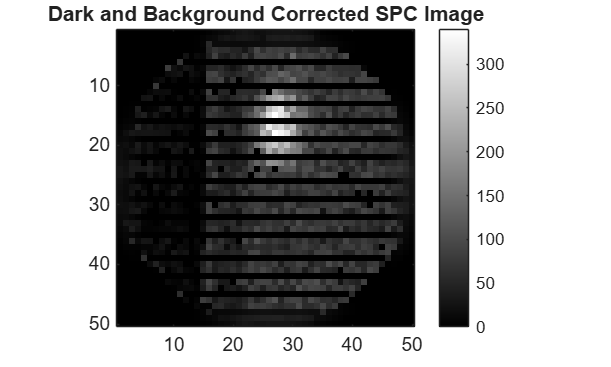




%% ============================================================
% DARK COUNT CORRECTION
% ============================================================

% Detector parameters

INTEGRATION_TIME = 0.1;     % seconds
DARK_COUNT_RATE = 250;       % counts/sec


Dark_counts = DARK_COUNT_RATE * INTEGRATION_TIME;


% subtract detector dark counts

SPC_corrected = SPC_frame - Dark_counts;


% remove negative counts

SPC_corrected(SPC_corrected < 0)=0;



%% ============================================================
% BACKGROUND CORRECTION
% ============================================================


background = median(SPC_corrected(:));


Photon_image = SPC_corrected - background;


Photon_image(Photon_image < 0)=0;



%% ============================================================
% PSF MODEL
% Equivalent to Task 8 Gaussian PSF
% ============================================================

PSF_SIGMA = 1.2;


PSF = fspecial('gaussian',[7 7],PSF_SIGMA);



%% ============================================================
% EDGE CORRECTION FOR RL
% ============================================================

Photon_image = edgetaper(Photon_image,PSF);



%% ============================================================
% RICHARDSON-LUCY RECONSTRUCTION
% ============================================================

iterations = 20;


RL_image = deconvlucy(Photon_image,PSF,iterations);



%% ============================================================
% DISPLAY CORRECTED IMAGE
% ============================================================

figure

imagesc(Photon_image)

axis image
axis ij
colormap(gray)
colorbar

title('Dark and Background Corrected SPC Image')

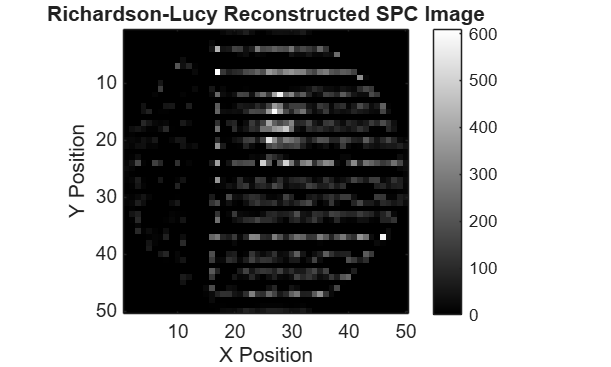




%% ============================================================
% DISPLAY RL RESULT
% ============================================================

figure

imagesc(RL_image)

axis image
axis ij
colormap(gray)
colorbar

title('Richardson-Lucy Reconstructed SPC Image')

xlabel('X Position')
ylabel('Y Position')